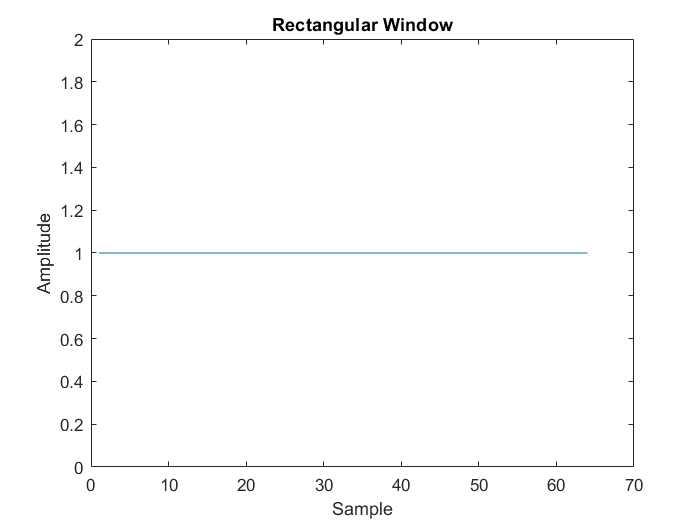

alpha = 1 + mod(509,3);
alpha= 1 +mod(509,3);
% Define the length of the window
N = 64;

% Define the windows
rectangular_window = ones(1, N);
hamming_window = hamming(N);
hanning_window = hanning(N);

window_length = 64;
rectangular_window = ones(1, window_length);

% Plot the rectangular window
figure;
plot(rectangular_window);
title('Rectangular Window');
xlabel('Sample');
ylabel('Amplitude');

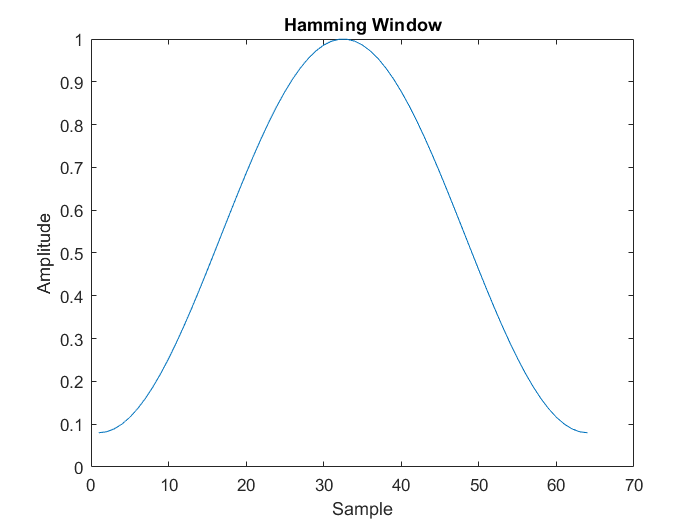


window_length = 64;
hamming_window = hamming(window_length);

% Plot the Hamming window
figure;
plot(hamming_window);
title('Hamming Window');
xlabel('Sample');
ylabel('Amplitude');

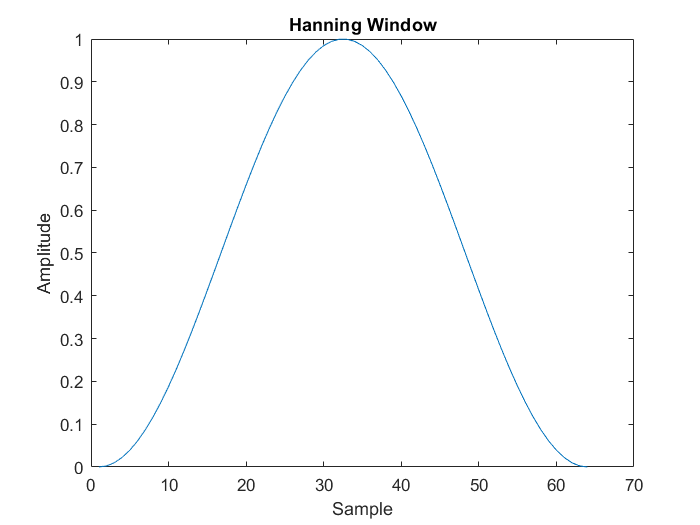


window_length = 64;
hanning_window = hann(window_length);

% Plot the Hanning window
figure;
plot(hanning_window);
title('Hanning Window');
xlabel('Sample');
ylabel('Amplitude');

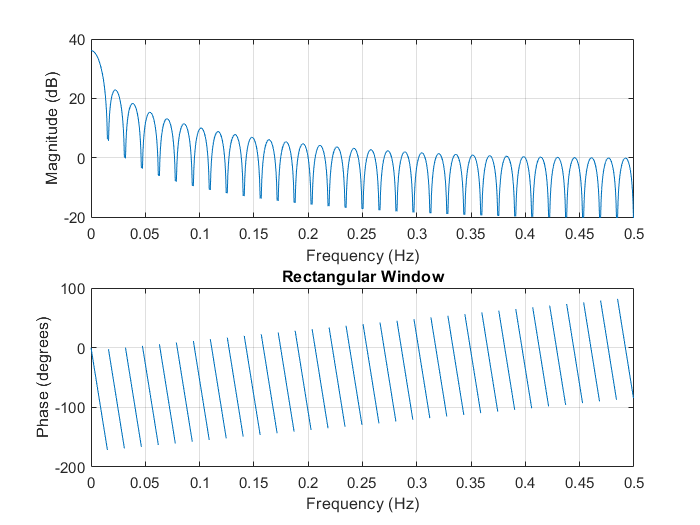



% Compute the frequency response using freqz
figure;
freqz(rectangular_window, 1, 1024, 1);
title('Rectangular Window');

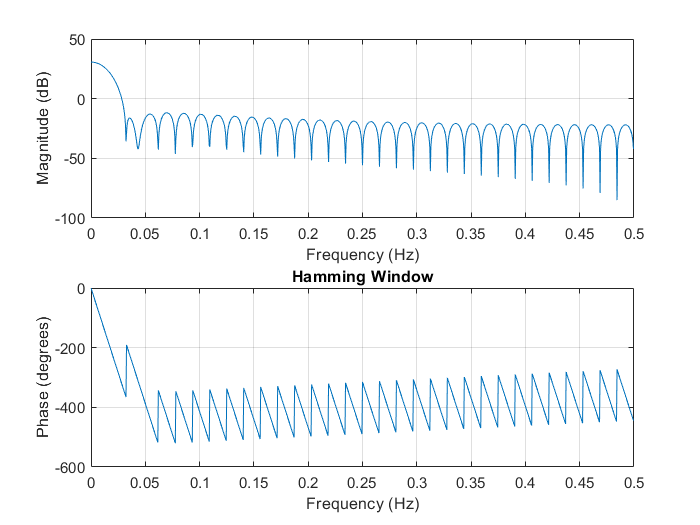


figure;
freqz(hamming_window, 1, 1024, 1);
title('Hamming Window');

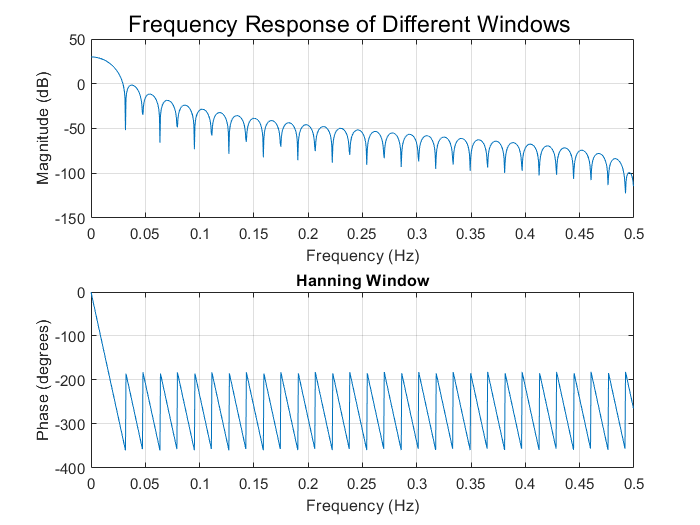


figure;
freqz(hanning_window, 1, 1024, 1);
title('Hanning Window');

% Adjust the figure layout
sgtitle('Frequency Response of Different Windows');

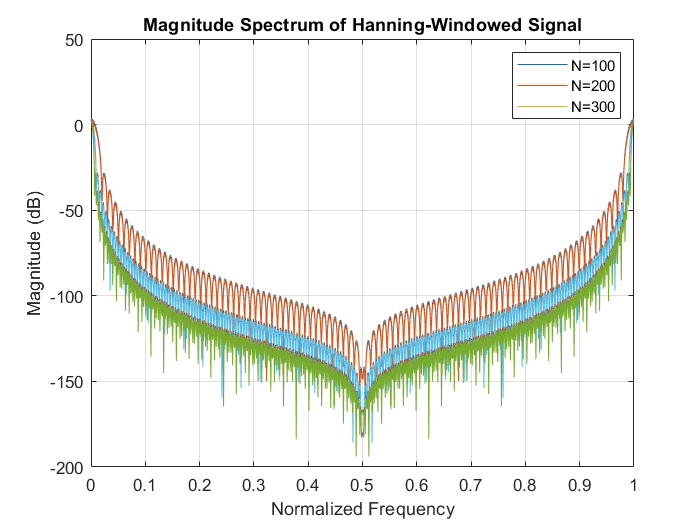

%%%%%% 1-b
alpha = 3;  % Set the value of alpha

% Define the different lengths
N_values = [100, 200, 300];

% Number of points for the DFT
N_DFT = 1024;

% Create a frequency axis for the DFT
freq_axis = (0:N_DFT-1) / N_DFT;

% Loop through different lengths
for N = N_values
    % Generate the Hanning window
    hanning_window = hann(N);
   
    % Generate a signal (e.g., a sine wave)
    t = 0:1/N:(N-1)/N;
    signal = alpha * cos(2 * pi * 0.1 * t); % Example signal with a cosine component
   
    % Apply the Hanning window to the signal
    windowed_signal = signal .* hanning_window;
   
    % Compute the DFT of the windowed signal
    dft = fft(windowed_signal, N_DFT);
   
    % Normalize the magnitude by the actual length
    normalized_magnitude = abs(dft) / N;
   
    % Plot the magnitude spectrum
    plot(freq_axis, 20*log10(normalized_magnitude));
    hold on;
end

% Label the plot and add a legend
title('Magnitude Spectrum of Hanning-Windowed Signal');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('N=100','N=200','N=300');

% Set grid and hold off
grid on;
hold off;

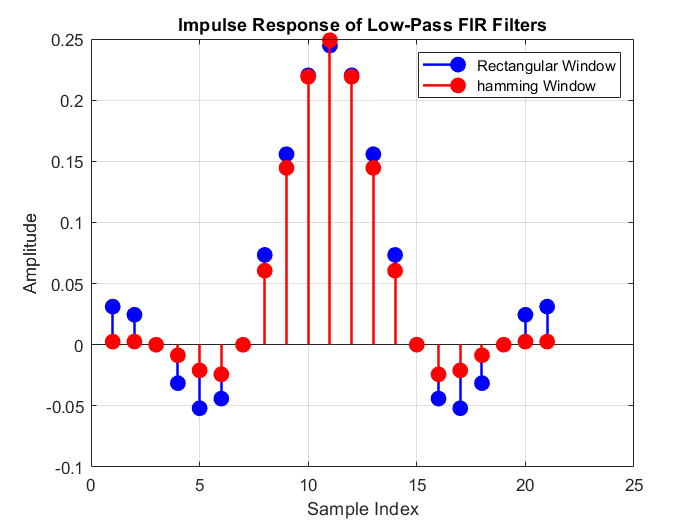

%%%%%% 2
alpha = 3; % hamming window
window_length = 21;
cutoff_frequency = pi / (alpha + 1);

% Design FIR filters with different windows
rectangular_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', rectwin(window_length));
hamming_filter = fir1(window_length-1, cutoff_frequency/(pi), 'low', hamming(window_length));

% Impulse responses on the same graph using different colors
figure;
stem(rectangular_filter, 'b', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
hold on;
stem(hamming_filter, 'r', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'r');
hold off;
title('Impulse Response of Low-Pass FIR Filters');
xlabel('Sample Index');
ylabel('Amplitude');
legend('Rectangular Window', 'hamming Window');
grid on;

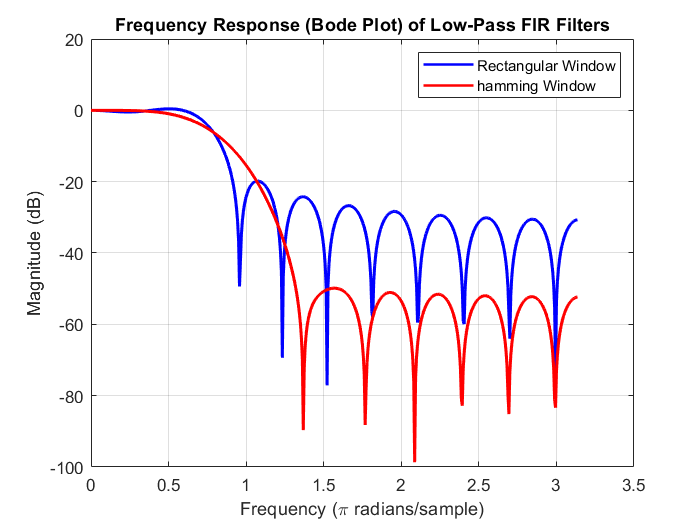


% Frequency responses on the same graph using different colors
[frequency_response_rect, freq_rect] = freqz(rectangular_filter, 1, 'half');
[frequency_response_hamming, freq_hamming] = freqz(hamming_filter, 1, 'half');

figure;
plot(freq_rect, 20*log10(abs(frequency_response_rect)), 'b', 'LineWidth', 1.5);
hold on;
plot(freq_hamming, 20*log10(abs(frequency_response_hamming)), 'r', 'LineWidth', 1.5);
hold off;
title('Frequency Response (Bode Plot) of Low-Pass FIR Filters');
xlabel('Frequency (\pi radians/sample)');
ylabel('Magnitude (dB)');
legend('Rectangular Window', 'hamming Window');
grid on;


% Comment on the filters
disp('The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the hamming window filter.');

The rectangular window filter has a sharper transition band and higher stopband attenuation compared to the hamming window filter.


%%%%%% 3
% Load the audio file
[y, fs] = audioread('instru3.wav');
% Compute the DFT of the audio signal
N = length(y);
dft = fft(y, N);

figure
spectrogram(y,hamming(512),256,512,fs, 'yaxis');
title('Spectrogram of Original Audio');

% Compute the magnitude spectrum of the DFT
magnitude_spectrum = abs(dft);
% Calculate the fundamental frequency (excluding DC component)
[~, peak_index] = max(magnitude_spectrum(2:end));
fundamental_frequency = peak_index * fs / N
% Define the desired band-pass frequency range (in Hz)
low_cutoff = fundamental_frequency - 20; % Adjust as needed
high_cutoff = fundamental_frequency + 20; % Adjust as needed
% Normalize the cutoff frequencies to the Nyquist rate
nyquist_freq = fs / 2;
low_cutoff_normalized = low_cutoff / nyquist_freq;
high_cutoff_normalized = high_cutoff / nyquist_freq;
% Design a band-pass FIR filter using the Hamming window
filter_order = 63; % Adjust the filter order as needed
filter_coefficients = fir1(filter_order, [low_cutoff_normalized, high_cutoff_normalized], 'bandpass', hamming(filter_order + 1));
% Apply the FIR filter to the audio signal
filtered_audio = filter(filter_coefficients, 1, y);
% Normalize the filtered audio
filtered_audio = filtered_audio / max(abs(filtered_audio));
% Write the filtered audio to a new .wav file
audiowrite('filtered_instru_bandpass.wav', filtered_audio, fs);
% Play the filtered audio
sound(filtered_audio, fs);
% Compute and plot the spectrogram of the filtered audio
figure;
spectrogram(filtered_audio, hamming(512), 256, 512, fs, 'yaxis');
title('Spectrogram of Band-Pass Filtered Audio (Fundamental and Harmonics)');

%%%%%% 4

